# Análisis de los experimentos con especies virtuales

load Test2_SA_05_NoAlpha.mat

PointsAux = Points;
CoeffsAux = Coeffs;
DistanceMetricAux = DistanceMetric;
AreaMetricAux = AreaMetric;

load Test3_SA_05_NoAlpha.mat

Points = [PointsAux; Points];
Coeffs = [CoeffsAux; Coeffs];
DistanceMetric = [DistanceMetricAux, DistanceMetric];
AreaMetric = [AreaMetricAux, AreaMetric];

clear PointsAux CoeffsAux DistanceMetricAux AreaMetricAux

1. Criterio gráfico

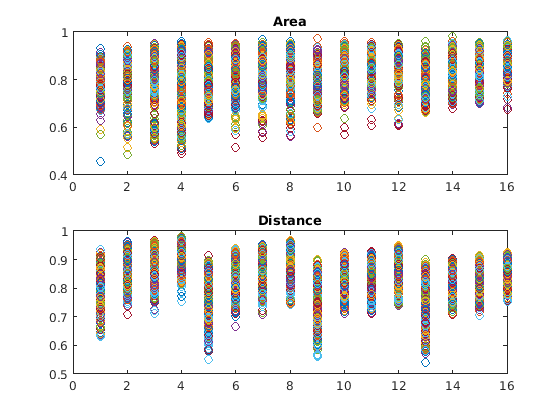

close all
subplot(2,1,1)
plot(AreaMetric, 'o')
title('Area')
subplot(2,1,2)
plot(DistanceMetric, 'o')
title('Distance')

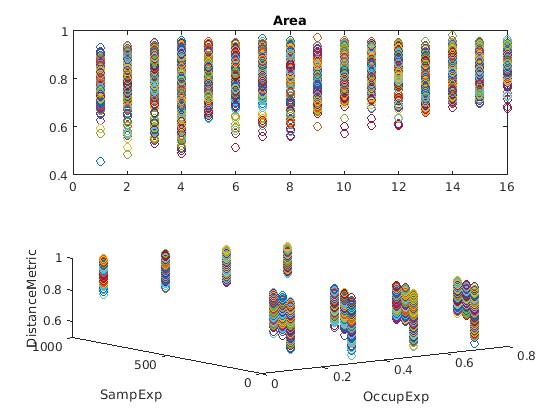

% plot3(OccupExp,SampExp,DistanceMetric, 'o')
% xlabel('OccupExp')
% ylabel('SampExp')
% zlabel('DistanceMetric')

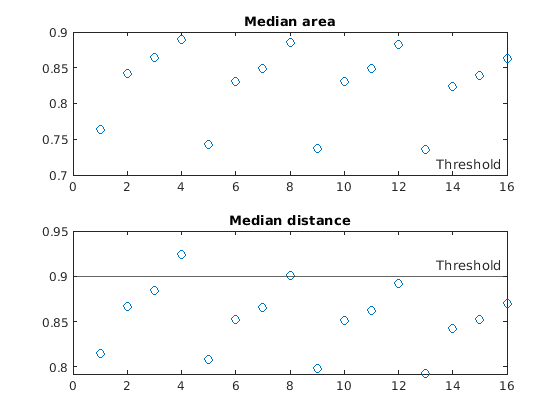

close all
MedianDistance = median(DistanceMetric');
MedianArea = median(AreaMetric');
TresArea = 0.7;
TresDist = 0.9;

subplot(2,1,1)
plot(MedianArea, 'o')
hold on
yline(TresArea,'-','Threshold');
title('Median area')

subplot(2,1,2)
plot(MedianDistance, 'o')
hold on
yline(TresDist,'-','Threshold');
title('Median distance')

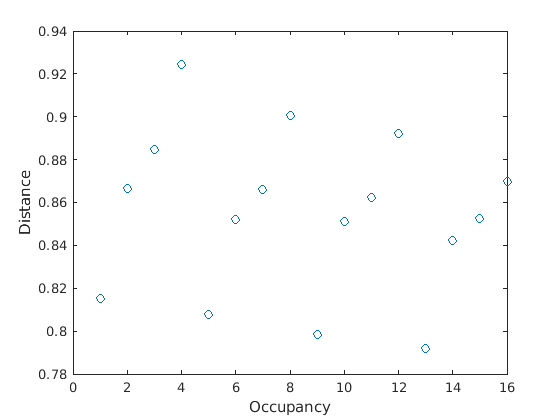

figure
[~, idxOcc] = sort(OccupExp);
plot(MedianDistance(idxOcc),'o');
xlabel('Occupancy')
ylabel('Distance')

## Best Parameter Combination

AreaPoints = find(MedianArea >= TresArea);
DistancePoints = find(MedianDistance >= TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 2

Kruskal-Wallis Test

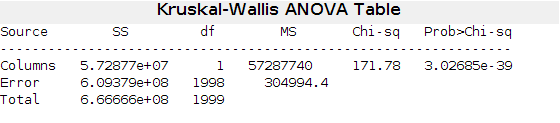

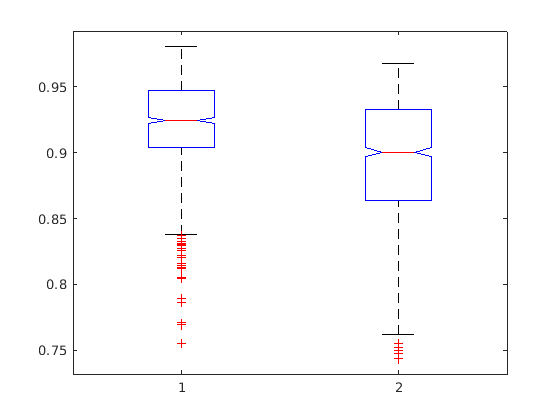

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

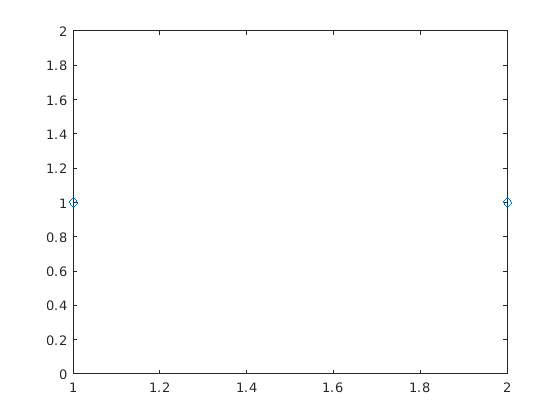

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 2
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:2


Samples:1000


Occupation:0.1


alpha:2


Samples:1000


Occupation:0.3


## Worst parameter combination

AreaPoints = find(MedianArea < TresArea);
DistancePoints = find(MedianDistance < TresDist);

sum(ismember(AreaPoints, DistancePoints))

ans = 0

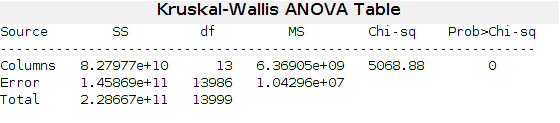

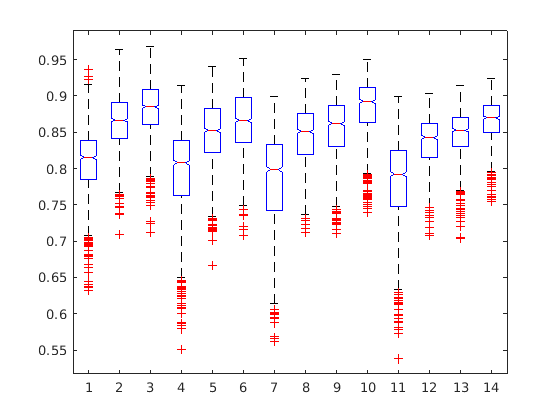

SelectedDistance = DistanceMetric(DistancePoints,:)';
p = kruskalwallis(SelectedDistance);

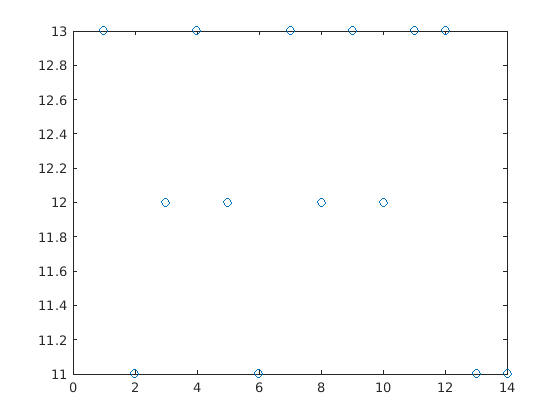

N = length(DistancePoints);
RankSumTestP = zeros(N,N);
RankSumTestBool = zeros(N,N);

for i = 1 : N
    for j = 1 : N
        RankSumTestP(i, j) = ranksum(SelectedDistance(:, i), SelectedDistance(:, j));
        %null hypothesis: data in x and y are samples from continuous distributions with equal medians
        if RankSumTestP(i, j) <= 0.05 %reject null (?)
            RankSumTestBool(i, j) = 1;
        end
    end
end

[Max, idx] = max(mean(SelectedDistance));
Comparation = sum(RankSumTestBool');
plot(Comparation, 'o')

[~, indexBest] = sort(Comparation, 'descend');
for i = 1 : 6
    j = DistancePoints(indexBest(i));
    disp(" ")
    disp("alpha:" + alpExp(j))
    disp("Samples:" + SampExp(j))
    disp("Occupation:" + OccupExp(j))
end

alpha:2


Samples:10


Occupation:0.1


alpha:2


Samples:10


Occupation:0.3


alpha:2


Samples:10


Occupation:0.5


alpha:2


Samples:100


Occupation:0.5


alpha:2


Samples:10


Occupation:0.7


alpha:2


Samples:50


Occupation:0.7


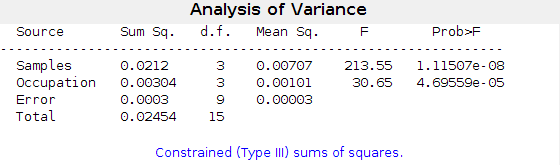

% [~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp},'model','interaction','varnames',{'Samples','Occupation'});
[~,~,stats] = anovan(mean(DistanceMetric, 2),{SampExp, OccupExp},'model','linear','varnames',{'Samples','Occupation'});

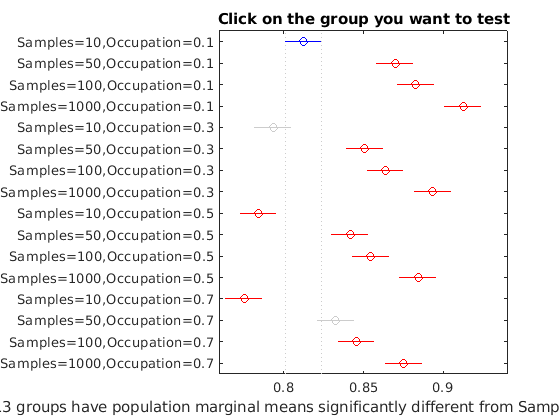

results = multcompare(stats,'Dimension',[1 2]);